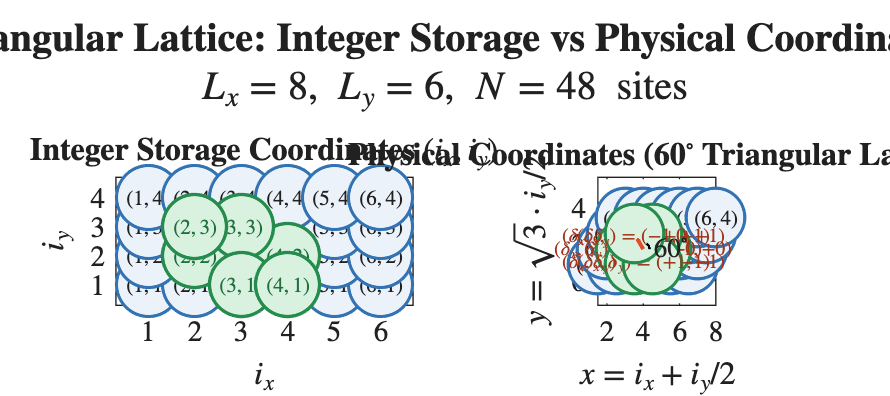

%% Triangular Lattice Schematic
%  Illustrates:
%  1. Integer storage coordinates (ix, iy)
%  2. Physical coordinates x = ix + iy/2, y = sqrt(3)/2 * iy
%  3. Six nearest-neighbour directions
%  4. Periodic boundary conditions (wrap-around edges)

clear; clc; close all;

Lx = 6;  Ly = 4;

%% Compute physical coordinates for each site
X = zeros(Lx, Ly);
Y = zeros(Lx, Ly);
for iy = 1:Ly
    for ix = 1:Lx
        X(ix,iy) = ix + 0.5*iy;
        Y(ix,iy) = sqrt(3)/2 * iy;
    end
end

%% Neighbour offsets (triangular lattice)
nn_dix = [+1, -1,  0,  0, +1, -1];
nn_diy = [ 0,  0, +1, -1, -1, +1];

%% ── Figure Setup & Style Defaults ────────────────────────────
fig = figure('Color','white','Position',[100 100 1100 490]);

% 设置全局默认属性，确保 Times New Roman 和 LaTeX 完美契合
set(fig, 'DefaultTextInterpreter', 'latex');
set(fig, 'DefaultAxesTickLabelInterpreter', 'latex');
set(fig, 'DefaultLineLineJoin', 'round');

% 定义学术出版级配色方案
font_name = 'Times New Roman';
color_bg_lines   = [0.80 0.82 0.85]; % 内部网格线：淡雅灰蓝
color_wrap_lines = [0.85 0.35 0.25]; % 周期性边界：珊瑚红虚线
color_arrow      = [0.90 0.30 0.15]; % 邻居方向箭头

color_site_face   = [0.92 0.95 0.98]; % 普通节点填充：浅蓝
color_site_edge   = [0.20 0.45 0.70]; % 普通节点边框：深海蓝

color_cent_face   = [1.00 0.88 0.50]; % 中心节点填充：柔和金
color_cent_edge   = [0.75 0.45 0.00]; % 中心节点边框：琥珀棕

color_nb_face     = [0.85 0.95 0.88]; % 邻居节点填充：莫兰迪绿
color_nb_edge     = [0.15 0.55 0.30]; % 邻居节点边框：深林绿

%% ── Left panel: integer storage coordinates ──────────────────
subplot(1,2,1);
hold on;

% Draw edges in integer space (regular square-ish grid)
for iy = 1:Ly
    for ix = 1:Lx
        for k = 1:6
            nx = mod(ix-1+nn_dix(k), Lx) + 1;
            ny = mod(iy-1+nn_diy(k), Ly) + 1;
            % Only draw non-periodic edges to keep it clean
            if abs(nx-ix) <= 1 && abs(ny-iy) <= 1
                plot([ix nx],[iy ny],'-','Color',color_bg_lines,'LineWidth',0.9);
            end
        end
    end
end

% Draw periodic boundary wrap lines (dashed, colored)
for iy = 1:Ly
    for ix = 1:Lx
        for k = 1:6
            nx = mod(ix-1+nn_dix(k), Lx) + 1;
            ny = mod(iy-1+nn_diy(k), Ly) + 1;
            % Detect wrap-around
            is_wrap = (abs(nx-ix) > 1) || (abs(ny-iy) > 1);
            if is_wrap
                plot([ix nx],[iy ny],'--','Color',color_wrap_lines,'LineWidth',1.1);
            end
        end
    end
end

% Draw sites
for iy = 1:Ly
    for ix = 1:Lx
        plot(ix, iy, 'o', 'MarkerSize', 24, ...
            'MarkerFaceColor', color_site_face, ...
            'MarkerEdgeColor', color_site_edge, ...
            'LineWidth', 1.2);
        text(ix, iy, sprintf('$(%d,%d)$',ix,iy), ...
            'HorizontalAlignment','center', ...
            'VerticalAlignment','middle', ...
            'FontSize', 8, 'FontName', font_name);
    end
end

% Highlight one site and its 6 neighbours
cx = 3; cy = 2;
nn_sites = zeros(6,2);
for k = 1:6
    nn_sites(k,1) = mod(cx-1+nn_dix(k), Lx) + 1;
    nn_sites(k,2) = mod(cy-1+nn_diy(k), Ly) + 1;
end

% Highlight centre
plot(cx, cy, 'o', 'MarkerSize', 24, ...
    'MarkerFaceColor', color_cent_face, ...
    'MarkerEdgeColor', color_cent_edge, 'LineWidth', 1.6);
text(cx, cy, sprintf('$(%d,%d)$',cx,cy), ...
    'HorizontalAlignment','center','VerticalAlignment','middle',...
    'FontSize',8,'FontWeight','bold', 'FontName', font_name);

% Highlight neighbours
for k = 1:6
    nx = nn_sites(k,1);  ny = nn_sites(k,2);
    is_wrap = (abs(nx-cx) > 1) || (abs(ny-cy) > 1);
    if ~is_wrap
        plot(nx, ny, 'o', 'MarkerSize', 24, ...
            'MarkerFaceColor', color_nb_face, ...
            'MarkerEdgeColor', color_nb_edge, 'LineWidth', 1.3);
        text(nx, ny, sprintf('$(%d,%d)$',nx,ny), ...
            'HorizontalAlignment','center','VerticalAlignment','middle',...
            'FontSize',8,'Color',color_nb_edge*0.8, 'FontName', font_name);
    end
end

% Axes and labels
xlabel('$i_x$', 'FontSize',14, 'FontName', font_name);
ylabel('$i_y$', 'FontSize',14, 'FontName', font_name);
title('\textbf{Integer Storage Coordinates } $(i_x, i_y)$', ...
    'FontSize',13, 'FontName', font_name);
xlim([0.3 Lx+0.7]);  ylim([0.3 Ly+0.7]);
set(gca,'XTick',1:Lx,'YTick',1:Ly,'FontSize',11,'Box','on', 'FontName', font_name);
grid off;


%% ── Right panel: physical coordinates ────────────────────────
subplot(1,2,2);
hold on;

% Draw all edges in physical space
for iy = 1:Ly
    for ix = 1:Lx
        x0 = X(ix,iy);  y0 = Y(ix,iy);
        for k = 1:6
            nx_i = mod(ix-1+nn_dix(k), Lx) + 1;
            ny_i = mod(iy-1+nn_diy(k), Ly) + 1;
            x1 = X(nx_i, ny_i);  y1 = Y(nx_i, ny_i);
            is_wrap = (abs(nx_i-ix) > 1) || (abs(ny_i-iy) > 1);
            if ~is_wrap
                plot([x0 x1],[y0 y1],'-','Color',color_bg_lines,'LineWidth',0.9);
            else
                plot([x0 x1],[y0 y1],'--','Color',color_wrap_lines,'LineWidth',1.1);
            end
        end
    end
end

% Draw sites
for iy = 1:Ly
    for ix = 1:Lx
        plot(X(ix,iy), Y(ix,iy), 'o', 'MarkerSize', 22, ...
            'MarkerFaceColor', color_site_face, ...
            'MarkerEdgeColor', color_site_edge, 'LineWidth', 1.2);
        text(X(ix,iy), Y(ix,iy), sprintf('$(%d,%d)$',ix,iy), ...
            'HorizontalAlignment','center','VerticalAlignment','middle',...
            'FontSize',8, 'FontName', font_name);
    end
end

% Highlight centre site in physical space
plot(X(cx,cy), Y(cx,cy), 'o', 'MarkerSize', 22, ...
    'MarkerFaceColor', color_cent_face, ...
    'MarkerEdgeColor', color_cent_edge, 'LineWidth', 1.6);

% Highlight neighbours and draw arrows with offset labels
for k = 1:6
    nx_i = nn_sites(k,1);  ny_i = nn_sites(k,2);
    is_wrap = (abs(nx_i-cx) > 1) || (abs(ny_i-cy) > 1);
    if ~is_wrap
        plot(X(nx_i,ny_i), Y(nx_i,ny_i), 'o', 'MarkerSize', 22, ...
            'MarkerFaceColor', color_nb_face, ...
            'MarkerEdgeColor', color_nb_edge, 'LineWidth', 1.2);
        
        % Arrow from centre to neighbour
        dx = X(nx_i,ny_i) - X(cx,cy);
        dy = Y(nx_i,ny_i) - Y(cx,cy);
        quiver(X(cx,cy), Y(cx,cy), dx*0.58, dy*0.58, 0, ...
            'Color',color_arrow,'LineWidth',1.5,...
            'MaxHeadSize',0.5,'AutoScale','off');
        
        % Label the offset using LaTeX math mode
        mx = X(cx,cy) + dx*0.82;
        my = Y(cx,cy) + dy*0.82;
        text(mx, my, sprintf('$(\\delta_x,\\delta_y)=(%+d,%+d)$',...
            nn_dix(k), nn_diy(k)), ...
            'FontSize',7.5,'Color',color_arrow*0.7, ...
            'HorizontalAlignment','center', 'FontName', font_name);
    end
end

% Annotate 60-degree bond angle
theta = linspace(0, pi/3, 30);
r_arc = 0.35;
plot(X(cx,cy) + r_arc*cos(theta), Y(cx,cy) + r_arc*sin(theta), ...
    'k-', 'LineWidth', 1.0);
text(X(cx,cy)+0.42, Y(cx,cy)+0.22, '$60^\circ$', 'FontSize',10, 'FontName', font_name);

xlabel('$x = i_x + i_y/2$', 'FontSize',14, 'FontName', font_name);
ylabel('$y = \sqrt{3} \cdot i_y / 2$', 'FontSize',14, 'FontName', font_name);
title('\textbf{Physical Coordinates (60$^\circ$ Triangular Lattice)}', ...
    'FontSize',13, 'FontName', font_name);
axis equal;  grid off;
set(gca,'FontSize',11,'Box','on', 'FontName', font_name);

%% ── Global Title ─────────────────────────────────────────────
sgtitle({'\textbf{Triangular Lattice: Integer Storage vs Physical Coordinates}', ...
         '$L_x = 8, \ L_y = 6, \ N = 48 \mathrm{\ sites}$'}, ...
    'FontSize', 15, 'FontName', font_name, 'Interpreter', 'latex');